# Example for using the `shade_tint_rgb` function.

Copyright © 2021 Tamas Kis

We want to draw two rows of 5 squares in a row:

- In both rows, the first square is green.

- In the first row, the squares are gradually tinted until the last square is white.

- In the second row, the squares are gradually shaded until the last square is black.

First, let's define the green color.

c = [0,1,0];

Finding the colors of the squares in the first row by tinting the green color,

c1_tint = shade_tint_rgb(c,0.25,'tint');
c2_tint = shade_tint_rgb(c,0.5,'tint');
c3_tint = shade_tint_rgb(c,0.75,'tint');
c4_tint = shade_tint_rgb(c,1,'tint');

Finding the colors of the squares in the second row by shading the green color,

c1_shade = shade_tint_rgb(c,0.25,'shade');
c2_shade = shade_tint_rgb(c,0.5,'shade');
c3_shade = shade_tint_rgb(c,0.75,'shade');
c4_shade = shade_tint_rgb(c,1,'shade');

Initialiize the figure for the plot.

figure;

Draw the first row of squares.

hold on;
rectangle('Position',[1,8,2,2],'facecolor',c);
rectangle('Position',[4,8,2,2],'facecolor',c1_tint);
rectangle('Position',[7,8,2,2],'facecolor',c2_tint);
rectangle('Position',[10,8,2,2],'facecolor',c3_tint);
rectangle('Position',[13,8,2,2],'facecolor',c4_tint);
hold off;

Draw the second row of squares.

hold on;
rectangle('Position',[1,1,2,2],'facecolor',c);
rectangle('Position',[4,1,2,2],'facecolor',c1_shade);
rectangle('Position',[7,1,2,2],'facecolor',c2_shade);
rectangle('Position',[10,1,2,2],'facecolor',c3_shade);
rectangle('Position',[13,1,2,2],'facecolor',c4_shade);
hold off;

Format the plot.

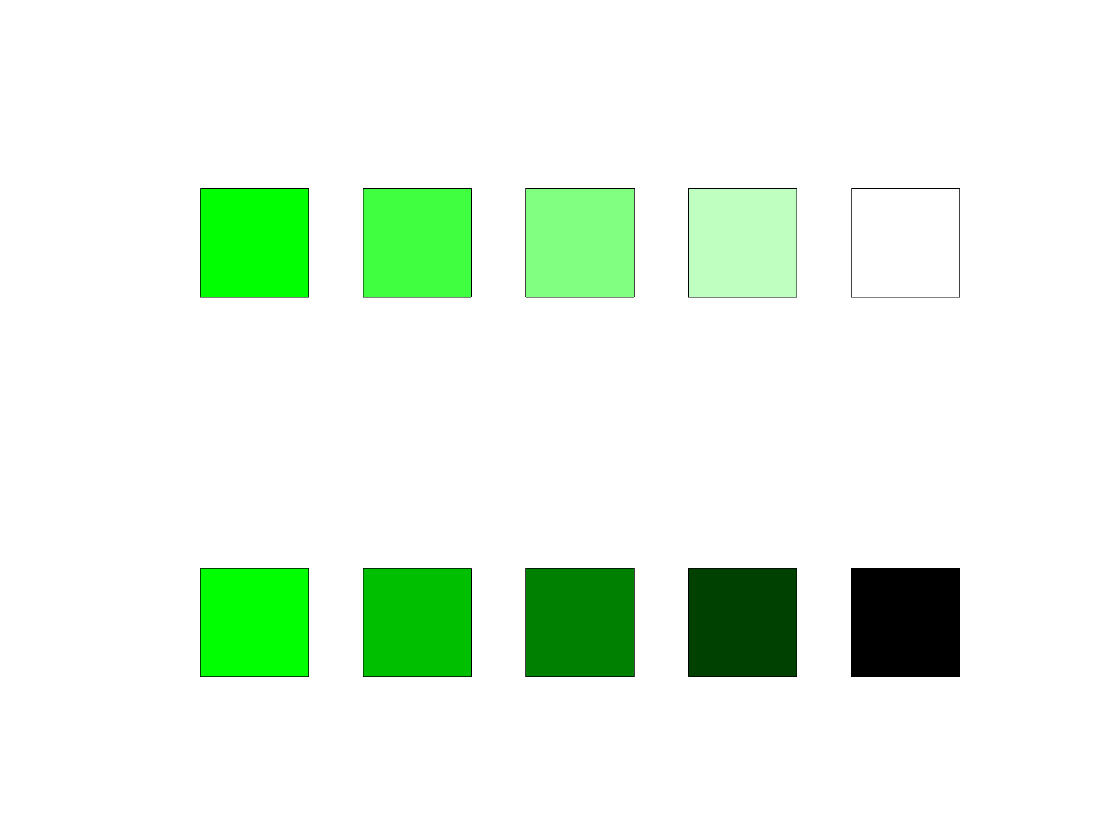

axis equal;
xlim([0,16]);
ylim([0,12]);
axis off;